clear all
close all
clc

## load example multisubject FC matrices

A = readNPY('adj_mus_dynamic.npy')

A = 16×2×100×100 int64 数组
A(:,:,1,1) =

   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0


A(:,:,2,1) =

   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   1


A(:,:,3,1) =

   0   0
   0   1
   0   1
   0   0
   1   0
   0   0
   1   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   1   0
   1   0
   0   0


A(:,:,4,1) =

   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   1
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0


A(:,:,5,1) =

   1   0
   0   0
   1   0
   0   0
   1   0
   0   0
   0   0
   0   0
   0   0
   0   1
   0   0
   0   1
   0   0
   0   0
   1   1
   0   1


A(:,:,6,1) =

   0   1
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   1
   0   0
   1   0
   0   0
   0   1
   0   0
   0   0
   0   0


A(:,:,7,1) =



Z = readNPY('z_mus_dynamic.npy')

Z = 16×2×100 int64 数组
Z(:,:,1) =

   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0


Z(:,:,2) =

   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1


Z(:,:,3) =

   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1


Z(:,:,4) =

   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1
   1   1


Z(:,:,5) =

   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0


Z(:,:,6) =

   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0
   0   0


Z(:,:,7) =

   0   0
   0   0


A = A(:,:,1:5);
[N,~,T] = size(A);  % number of nodes/layers
C = cell(T,1);      % create cell array
for i = 1:T         % populate array
    C{i} = A(:,:,i); % i-th layer of A, 100*100
end

## set some parameters

gammarange = [min(A(:)),max(A(:))]; % range of gamma values to consider
omegarange = [-0.5,1.5];            % range of omega values to consider
samplesPerStage = 250;              % number of samples per stage (ideally should be large)
nstage = 5;                         % number of stages (ideally should be large)
keep = 20;                          % number of nearest neighbors
couplingtype = 'categorical';       % nature of interlayer coupling (could also be ordered)

## get initial estimate of boundaries

stage = 1/5, sample = 25/250
stage = 1/5, sample = 50/250
stage = 1/5, sample = 75/250
stage = 1/5, sample = 100/250
stage = 1/5, sample = 125/250
stage = 1/5, sample = 150/250
stage = 1/5, sample = 175/250
stage = 1/5, sample = 200/250
stage = 1/5, sample = 225/250
stage = 1/5, sample = 250/250
stage = 2/5, sample = 25/250
stage = 2/5, sample = 50/250
stage = 2/5, sample = 75/250
stage = 2/5, sample = 100/250
stage = 2/5, sample = 125/250
stage = 2/5, sample = 150/250
stage = 2/5, sample = 175/250
stage = 2/5, sample = 200/250
stage = 2/5, sample = 225/250
stage = 2/5, sample = 250/250
stage = 3/5, sample = 25/250
stage = 3/5, sample = 50/250
stage = 3/5, sample = 75/250
stage = 3/5, sample = 100/250
stage = 3/5, sample = 125/250
stage = 3/5, sample = 150/250
stage = 3/5, sample = 175/250
stage = 3/5, sample = 200/250
stage = 3/5, sample = 225/250
stage = 3/5, sample = 250/250
stage = 4/5, sample = 25/250
stage = 4/5, sample = 50/250
stage = 4/5, sample = 75/250
stage = 4/5, sample = 

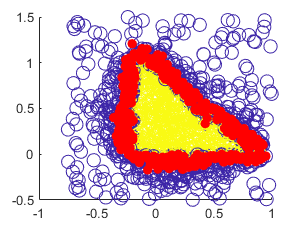

[gbound,obound,outputdata] = ...    % run boundary estimator
    fcn_get_bounds(C,gammarange,omegarange,samplesPerStage,nstage,keep,couplingtype);

## sample from within those boundaries

sample 1/1000, 0 try, elapsed time of 0.08 s
sample 2/1000, 0 try, elapsed time of 0.65 s
sample 3/1000, 0 try, elapsed time of 1.24 s
sample 4/1000, 0 try, elapsed time of 1.39 s
sample 5/1000, 0 try, elapsed time of 1.48 s
sample 6/1000, 0 try, elapsed time of 1.59 s
sample 7/1000, 0 try, elapsed time of 1.66 s
sample 8/1000, 0 try, elapsed time of 1.71 s
sample 9/1000, 0 try, elapsed time of 1.81 s
sample 10/1000, 0 try, elapsed time of 1.88 s
sample 11/1000, 0 try, elapsed time of 1.96 s
sample 12/1000, 0 try, elapsed time of 2.02 s
sample 13/1000, 0 try, elapsed time of 2.10 s
sample 14/1000, 0 try, elapsed time of 2.16 s
sample 15/1000, 0 try, elapsed time of 2.22 s
sample 16/1000, 0 try, elapsed time of 2.28 s
sample 17/1000, 0 try, elapsed time of 2.39 s
sample 18/1000, 0 try, elapsed time of 2.44 s
sample 19/1000, 0 try, elapsed time of 2.49 s
sample 20/1000, 0 try, elapsed time of 2.56 s
sample 21/1000, 0 try, elapsed time of 2.66 s
sample 22/1000, 0 try, elapsed time of 2.72

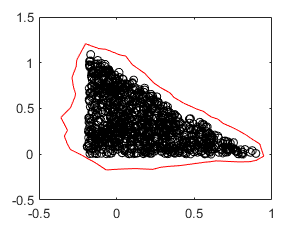

samplesTotal = 1000;                % total number of samples
[S,G,O] = fcn_staged_multilayer(C,gbound,obound,samplesTotal,couplingtype);

## calculate flexibility

switch couplingtype
    case 'categorical'
        [~,flx] = fcn_fastflx(S);
        flx = squeeze(nanmean(nanmean(flx,2),3));
    case 'ordered'
        flx = squeeze(nanmean(S(:,1:end - 1,:) ~= S(:,2:end,:),2));
end

## calculate node entropy and nonsingleton communities

ent = zeros(N,samplesTotal);        % preallocate array for entropy
nonsingle = zeros(samplesTotal,1);  % preallocate array for nonsingletons
for isample = 1:samplesTotal
    mx = max(max(S(:,:,isample)));  % max communities per sample
    bins = 1:mx;                    % bins
    h = hist(S(:,:,isample)',bins); % node histogram
    p = bsxfun(@rdivide,h,sum(h));  % probabilities
    e = -nansum(p.*log2(p));        % entropy
    ent(:,isample) = e;             % store
    h = hist(S(:,:,isample),bins);  % layer histogram
    nonsingle(isample,:) = ...      % number of nonsingletons
        nanmean(sum(h > 1));
end

## make some figures

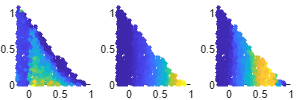

sz = 10;                            % size of points
f = fcn_rickplot([2,2,9,3]);        % create figure
vals = ...                          % concatenate variables
    [nanmean(ent)',squeeze(mean(max(S))),nonsingle];
for i = 1:3
    ax = axes('outerposition',[(i - 1)/3,0,1/3,1]);
    scatter(G,O,sz,vals(:,i),'filled');
end

## if you use this code, please cite: